# `3. Квантовое описание поляризации одиночных фотонов`

`Перейдем на новый уровень абстракции и для описания единичного фотона (вида винтовой линии) будем использовать следующий комплексный вектор, известный в оптике как `[вектор Джонса](https://ru.wikipedia.org/wiki/Формализм_Джонса)`:`

clear
syms E1 E2 k z omega t phi1 phi2
[E1*cos(k*z-omega*t+phi1);E2*cos(k*z-omega*t+phi2);0]   % ->

$$ans = \left(\begin{array}{c} E_{1}\,\cos\left(\varphi_{1}-\omega \,t+k\,z\right)\\ E_{2}\,\cos\left(\varphi_{2}-\omega \,t+k\,z\right)\\ 0 \end{array}\right)$$

ketphi=1/sqrt(E1^2+E2^2)* ...
[E1*exp(i*(k*z-omega*t+phi1));E2*exp(i*(k*z-omega*t+phi2))]        % (4)

$$ketphi = \left(\begin{array}{c} \frac{E_{1}\,{\mathrm{e}}^{\varphi_{1}\,\mathrm{i}-\omega \,t\,\mathrm{i}+k\,z\,\mathrm{i}}}{\sqrt{{E_{1}}^{2}+{E_{2}}^{2}}}\\ \frac{E_{2}\,{\mathrm{e}}^{\varphi_{2}\,\mathrm{i}-\omega \,t\,\mathrm{i}+k\,z\,\mathrm{i}}}{\sqrt{{E_{1}}^{2}+{E_{2}}^{2}}} \end{array}\right)$$

`в котором намеренно подчеркивается тот факт, что интенсивность нас теперь не интересует (мы имеем дело с одним фотоном).`

`Физически следующие записи состояния (4) эквивалентны:`

1/sqrt(E1^2+E2^2)* ...
[E1*exp(i*(k*z-omega*t+phi1));E2*exp(i*(k*z-omega*t+phi2))] % <->

$$ans = \left(\begin{array}{c} \frac{E_{1}\,{\mathrm{e}}^{\varphi_{1}\,\mathrm{i}-\omega \,t\,\mathrm{i}+k\,z\,\mathrm{i}}}{\sqrt{{E_{1}}^{2}+{E_{2}}^{2}}}\\ \frac{E_{2}\,{\mathrm{e}}^{\varphi_{2}\,\mathrm{i}-\omega \,t\,\mathrm{i}+k\,z\,\mathrm{i}}}{\sqrt{{E_{1}}^{2}+{E_{2}}^{2}}} \end{array}\right)$$

1/sqrt(E1^2+E2^2)* ...
[E1*exp(i*phi1);E2*exp(i*phi2)]      % <->

$$ans = \left(\begin{array}{c} \frac{E_{1}\,{\mathrm{e}}^{\varphi_{1}\,\mathrm{i}}}{\sqrt{{E_{1}}^{2}+{E_{2}}^{2}}}\\ \frac{E_{2}\,{\mathrm{e}}^{\varphi_{2}\,\mathrm{i}}}{\sqrt{{E_{1}}^{2}+{E_{2}}^{2}}} \end{array}\right)$$

1/sqrt(E1^2+E2^2)* ...
[E1;E2*exp(i*(phi2-phi1))] 

$$ans = \left(\begin{array}{c} \frac{E_{1}}{\sqrt{{E_{1}}^{2}+{E_{2}}^{2}}}\\ \frac{E_{2}\,{\mathrm{e}}^{-\varphi_{1}\,\mathrm{i}+\varphi_{2}\,\mathrm{i}}}{\sqrt{{E_{1}}^{2}+{E_{2}}^{2}}} \end{array}\right)$$

`Физическая эквивалентность означает, что все выводимые нами заключения о наблюдаемых экспериментально величинах должны быть одинаковы для перечисленных выше математических записей состояния.`

`Запишем некоторые состояния в новых обозначениях. Cостояние с горизонтальной поляризацией `$\left(E_1 \not= 0,E_2 =0\right):|H\rangle =\left\lbrack \begin{array}{c}
1\\
0
\end{array}\right\rbrack$. `Cостояние с вертикальной поляризацией `$\left(E_1 =0,E_2 \not= 0\right):|V\rangle =\left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack \ldotp$

`Произвольное состояние поляризации фотона имеет вид`

clear
syms c1 c2 ketpsi ketH ketV pi

$|\psi \rangle =\left\lbrack \begin{array}{c}
c_1 \\
c_2 
\end{array}\right\rbrack =c_1 \left\lbrack \begin{array}{c}
1\\
0
\end{array}\right\rbrack +c_2 \left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack =c_1 |H\rangle +c_2 |V\rangle$                  (6)

ketpsi=[c1;c2], ketpsi=c1*[1;0]+c2*[0;1], ketpsi=c1*ketH+c2*ketV

$$ketpsi = \left(\begin{array}{c} c_{1}\\ c_{2} \end{array}\right)$$

$$ketpsi = \left(\begin{array}{c} c_{1}\\ c_{2} \end{array}\right)$$

$$ketpsi = c_{1}\,\mathrm{ketH}+c_{2}\,\mathrm{ketV}$$

`где `$с_1 ,\;с_2 \in \mathbf{С},|c_1 |^2 +|c_2 |^2 =1$ `представляет собой суперпозицию состояний `$|H\rangle \;и\;|V\rangle$.

`Если аргументы `$\varphi_1$` и `$\varphi_2$ `комплексных чисел `$c_1$` и `$c_2$` совпадают или различаются на `$\pi$`, т.е. `$\varphi_1 =\varphi_2$` или `$\varphi_2 -\varphi_1 =\pm \pi$`, то имеем дело с линейной поляризацией (эллипс вырождается в прямую, рис.3).`

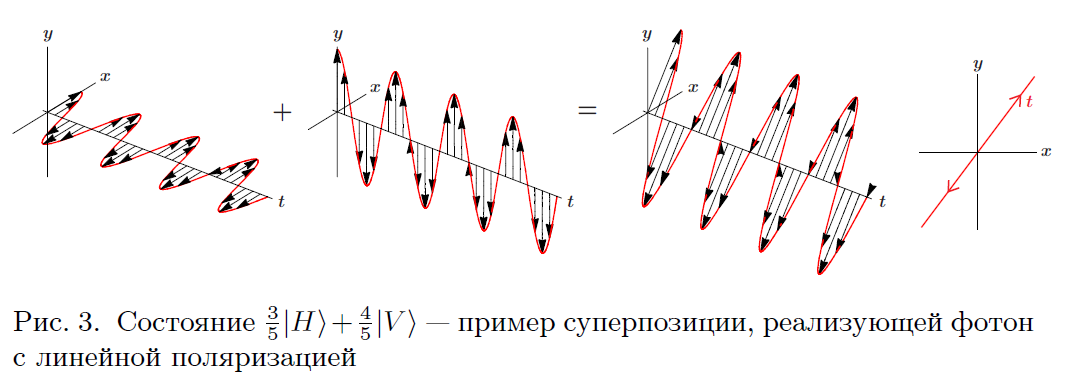

3/5*ketH+4/5*ketV

$$ans = \frac{3\,\mathrm{ketH}}{5}+\frac{4\,\mathrm{ketV}}{5}$$

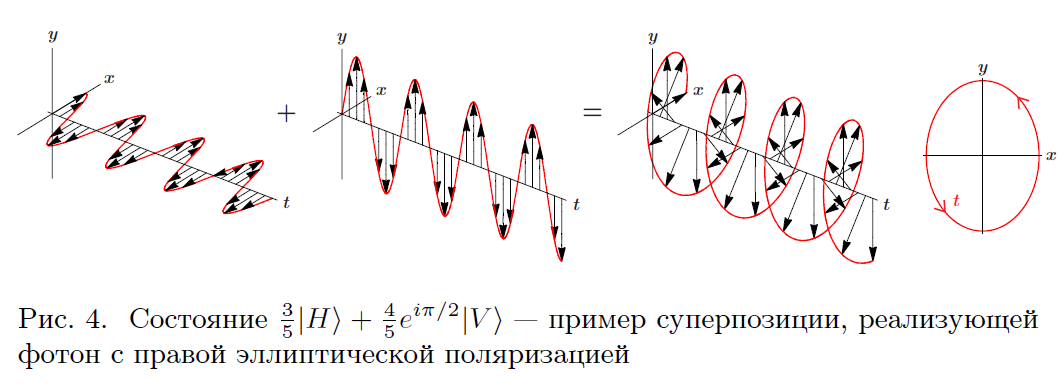

3/5*ketH+4/5*exp(i*pi/2)*ketV

$$ans = \frac{3\,\mathrm{ketH}}{5}+\frac{4\,\mathrm{ketV}\,\mathrm{i}}{5}$$

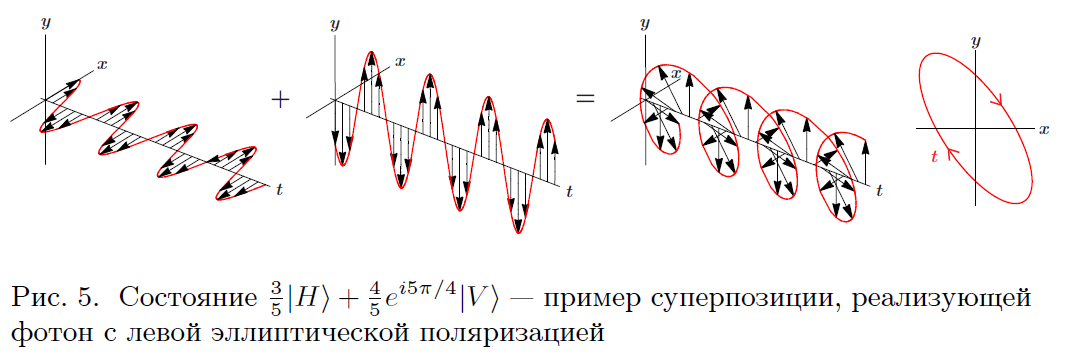

3/5*ketH+4/5*exp(i*5*pi/4)*ketV

$$ans = \frac{3\,\mathrm{ketH}}{5}+\sqrt{2}\,\mathrm{ketV}\,\left(-\frac{2}{5}-\frac{2}{5}\,\mathrm{i}\right)$$

`Умножение вектора `$|V\rangle$` на число `$|c_2 |e^{i\varphi_2 }$` означает, что амплитуда колебания вдоль оси `$y$` умножается на `$|c_2 |$`, а сама волна сдвинута по фазе на `$\varphi_2$ `(рис. 4 и 5).`

`Так, если `$\varphi_2 -\varphi_1 \in \left(0,\pi \right)$`, то c увеличением времени конец вектора ``E`` движется против часовой стрелки по эллипсу в плоскости ``xy`` (по кратчайшему повороту от ``x`` к ``y``). Такое состояние называют состоянием с правой эллиптической поляризацией [6, 7], поскольку это соответствует завинчиванию буравчика вдоль оси ``z`` и положительному моменту количества движения относительно направления распространения (рис. 6a).`

`Если `$\varphi_2 -\varphi_1 \in \left(\pi ,2\pi \right)$`, то c увеличением времени конец вектора ``E`` движется по часовой стрелке по эллипсу в плоскости ``xy`` (по кратчайшему повороту от ``y`` к ``x``). Такое состояние называют состоянием с левой эллиптической поляризацией [6, 7], поскольку это соответствует выкручиванию буравчика из оси z и отрицательному моменту количества движения относительно направления распространения (рис. 6b).`

`Если `$|c_1 |=|c_2 |$` и `$\varphi_2 -\varphi_1 =\frac{\pi }{2}$`, то имеем фотон с правой круговой поляризацией, вектор такого состояния `$|\mathrm{CL}\rangle =\frac{1}{\sqrt{2}}\left(|H\rangle +i|V\rangle \right)$

ketCL=1/sqrt(2)*(ketH+i*ketV)

$$ketCL = \frac{\sqrt{2}\,\left(\mathrm{ketH}+\mathrm{ketV}\,\mathrm{i}\right)}{2}$$

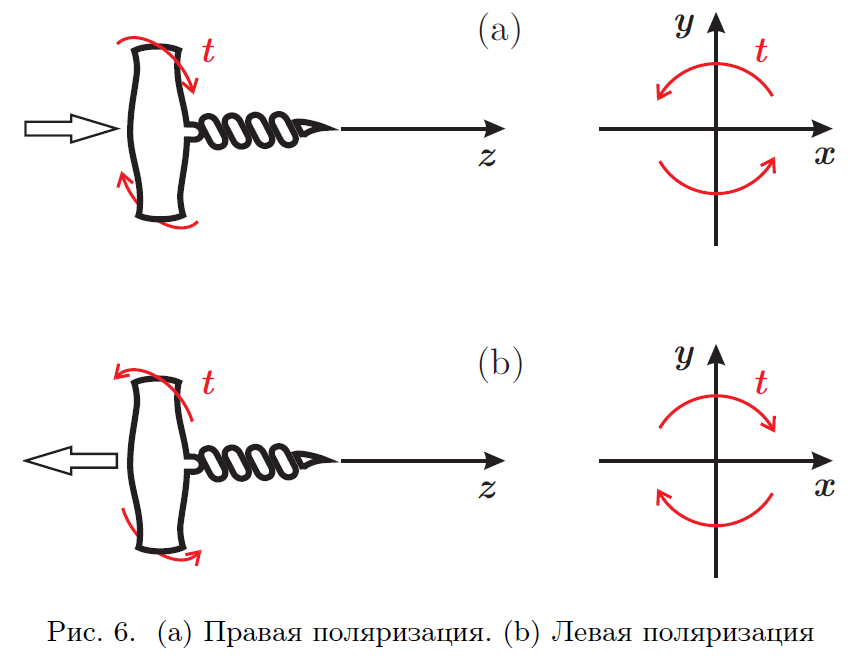

`Если `$\left|c_1 \left|=\right|c_2 \right|$` и `$\varphi_2 -\varphi_1 =\frac{3\pi }{2}$`, то имеем дело с левой круговой поляризацией, вектор такого состояния `$\left|\mathrm{CR}\right\rangle =\frac{1}{\sqrt{2}}\left(\left|H\right\rangle -i\left|V\right\rangle \right)$

ketCR=1/sqrt(2)*(ketH-i*ketV)

$$ketCR = \frac{\sqrt{2}\,\left(\mathrm{ketH}-\mathrm{ketV}\,\mathrm{i}\right)}{2}$$

`Мы увидели, что если отвлечься от условия `$\left|c_1 {\left|\right.}^2 +\right|c_2 {\left|\right.}^2 =1$` и отождествить состояния, отличающиеся лишь глобальным фазовым множителем, т.е. отождествить состояния `$|\psi \rangle$`и `$c|\psi \rangle ,c\in \mathbf{C},c\not= 0$`, то пространство векторов состояний будет линейным. Правило суперпозиции состояний тогда просто отражение линейности этого пространства. Следующий раздел посвящен краткому повторению соответствующей главы линейной алгебры.`